# **Controlador**

Se comienza por establecer el número de puntos en el trébol y la velocidad lineal esperada para el recorrido.

N = 100; %Número de puntos en el trébol
v = 10; %[cm/s]
pMax = 20*4; %Tomando el cuadro de 20 cm de lado
tRecorrido = pMax/v %[s]

tRecorrido = 8

tsMax = tRecorrido/N %[s]

tsMax = 0.0800

Teniendo en cuenta este tiempo de asentamiento, y que se espera un sobrepico mínimo.

as = 4.5/tsMax

as = 56.2500

Mp = 0.3

Mp = 0.3000

zeta = sqrt((log(Mp)^2)/(pi^2+(log(Mp)^2)))

zeta = 0.3579

Se comienza con el controlador del motor de la base, para el que se espera que no exista sobrepico y se debe tener un tiempo de establecimiento adecuado, es decir, menor al encontrado anteriormente.

%a = 0.7123;
%b = 3.634;
%G1 = tf([a],[1 b 0])

Km1 = 0.161%0.000631%0.161

Km1 = 0.1610

Tau1 = 21.889E-03 %[s]

Tau1 = 0.0219


G1 = tf(Km1,[Tau1 1 0])

G1 =
 
       0.161
  ---------------
  0.02189 s^2 + s
 
Continuous-time transfer function.



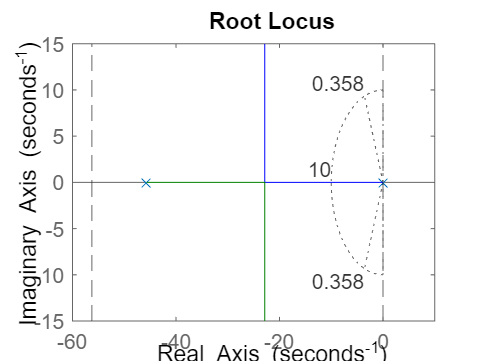

% t = linspace(0,TE1(end),length(TE1))
% y = step(G1,t)
% 
% plot(t,AngleE1)
% hold on
% plot(TE1,y,'r')
% xlabel('Tiempo [ms]')
% ylabel('Posición Angular [°]')
% legend('Datos Experimentales', 'Respuesta al paso FT',Location='northwest')
% title('Identificación planta junta 1')
% 
% 
% figure()
% plot(TE1,abs(y-AngleE1))
% xlabel('Tiempo [ms]')
% ylabel('Error de Posición Angular [°]')
% title('Error en la identificación planta junta 1')
% 
% figure()
% plot(TE1,100*abs(y-AngleE1)./AngleE1)
% xlabel('Tiempo [ms]')
% ylabel('Error porcentual [%]')
% title('Error porcentual en la identificación planta junta 1')
% 
% 
% 
% 
figure()
rlocus(G1)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kp1 = 22

kp1 = 22


G11 = tf([Km1 0],[Tau1 1 Km1*kp1])

G11 =
 
          0.161 s
  -----------------------
  0.02189 s^2 + s + 3.542
 
Continuous-time transfer function.



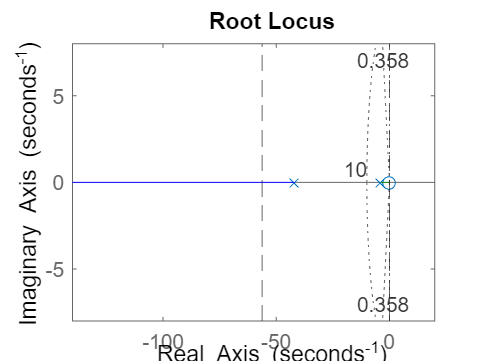


figure()
rlocus(G11)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kd1 = 0.03;

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



N = 100;
C1 = kp1 + kd1*(N/(1+(N*(1/s))))

C1 =
 
  25 s + 2200
  -----------
    s + 100
 
Continuous-time transfer function.



Go1 = C1*G1/(1+C1*G1)

Go1 =
 
                  0.0881 s^4 + 20.59 s^3 + 1532 s^2 + 35420 s
  ---------------------------------------------------------------------------
  0.0004791 s^6 + 0.1396 s^5 + 14.63 s^4 + 658.4 s^3 + 1.153e04 s^2 + 35420 s
 
Continuous-time transfer function.



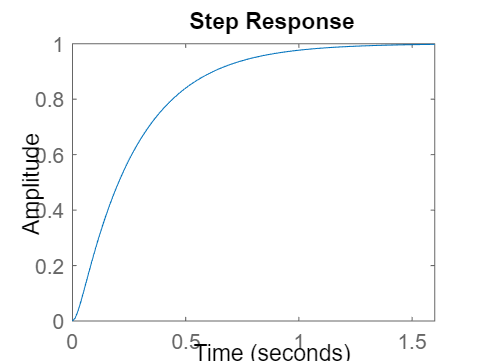

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 0.5748
    TransientTime: 1.0405
     SettlingTime: 1.0405
      SettlingMin: 0.9002
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 1.9036



%Openloop
Gol1 = G1*C1

Gol1 =
 
          4.025 s + 354.2
  -------------------------------
  0.02189 s^3 + 3.189 s^2 + 100 s
 
Continuous-time transfer function.



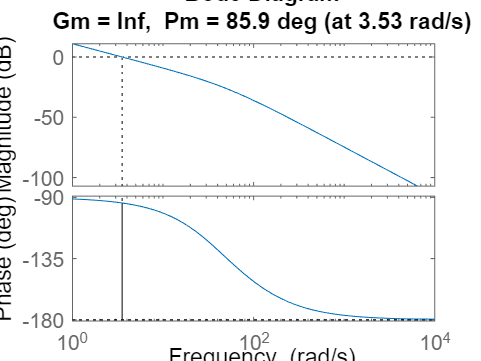

margin(Gol1)

Discretizar el controlador

Cz1 = c2d(C1,0.001,'least-squares')

Cz1 =
 
  24.86 z - 22.75
  ---------------
    z - 0.9044
 
Sample time: 0.001 seconds
Discrete-time transfer function.



a2 = 192.8;
b2 = 25.44;
G2 = tf(a2,[1 b2 0])

G2 =
 
      192.8
  -------------
  s^2 + 25.44 s
 
Continuous-time transfer function.




Km2 = 0.50796%0.001992%0.50796%*0.78431

Km2 = 0.5080

Tau2 = 51.00402E-03 %[s]

Tau2 = 0.0510



G2 = tf(Km2,[Tau2 1 0])

G2 =
 
      0.508
  -------------
  0.051 s^2 + s
 
Continuous-time transfer function.



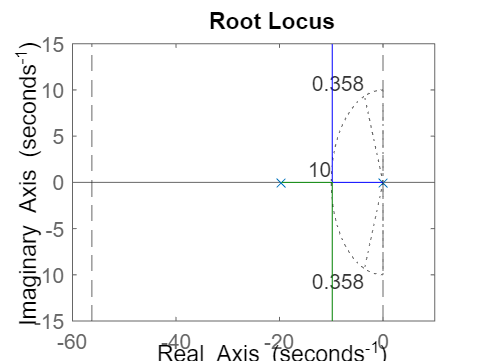


% t = linspace(0,TmsE2(end),length(TmsE2))
% y2 = step(G2,t)
% 
% plot(TmsE2,AngleE2)
% hold on
% plot(t,y2,'r')
% xlabel('Tiempo [ms]')
% xlim([0,180])
% ylabel('Posición Angular [°]')
% legend('Datos Experimentales', 'Respuesta al paso FT',Location='northwest')
% title('Identificación planta junta 2')
% 
% 
% figure()
% plot(TmsE2,abs(y2-AngleE2))
% xlabel('Tiempo [ms]')
% ylabel('Error en Posición Angular [°]')
% xlim([0,180])
% title('Error en la identificación planta junta 2')
% 
% 
% figure()
% plot(TmsE2,100*abs(y2-AngleE2)./AngleE2)
% xlabel('Tiempo [ms]')
% ylabel('Error Porcentual [%]')
% xlim([0,180])
% title('Error porcentual en la identificación planta junta 2')
% 
% 
figure()
rlocus(G2)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kp2 = 20

kp2 = 20


G22 = tf([Km2 0],[Tau2 1 Km2*kp2])

G22 =
 
         0.508 s
  ---------------------
  0.051 s^2 + s + 10.16
 
Continuous-time transfer function.



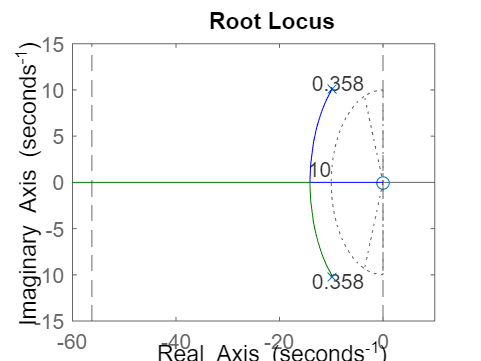


figure()
rlocus(G22)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kd2 = 0.866;

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



N = 100;
C2 = kp2 + kd2*(N/(1+(N*(1/s))))

C2 =
 
  106.6 s + 2000
  --------------
     s + 100
 
Continuous-time transfer function.



Go2 = C2*G2/(1+C2*G2)

Go2 =
 
               2.762 s^4 + 382.1 s^3 + 1.161e04 s^2 + 101592 s
  --------------------------------------------------------------------------
  0.002601 s^6 + 0.6223 s^5 + 50.18 s^4 + 1602 s^3 + 2.161e04 s^2 + 101592 s
 
Continuous-time transfer function.



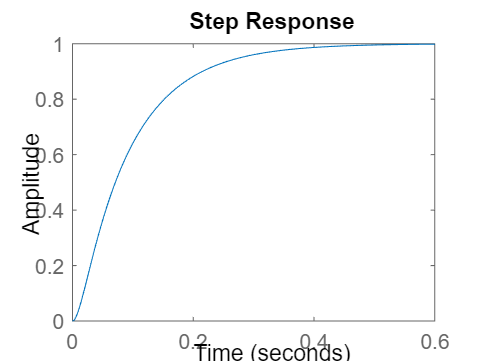

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 0.1969
    TransientTime: 0.3632
     SettlingTime: 0.3632
      SettlingMin: 0.9002
      SettlingMax: 0.9982
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9982
         PeakTime: 0.5867



%Openloop
Gol2 = G2*C2

Gol2 =
 
        54.15 s + 1016
  ---------------------------
  0.051 s^3 + 6.1 s^2 + 100 s
 
Continuous-time transfer function.



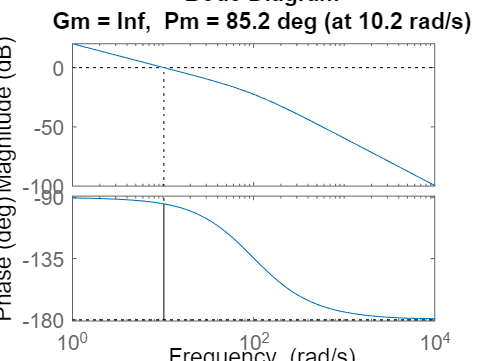

margin(Gol2)

Discretizar el controlador

Cz2 = c2d(C2,0.001,'least-squares')

Cz2 =
 
  102.4 z - 100.5
  ---------------
    z - 0.9044
 
Sample time: 0.001 seconds
Discrete-time transfer function.

